# **EXTRACTION OF MAXIMUM FREQUENCY (SUBJECT 2)**

To extract Maximum Frequency we consider Postural Tremor (TASK AS315).

clear all
close all
clc 

dati = load("Subj.mat");

**INDEX FINGER**

Time and sample frequency extraction.

p_tremor_dito_tempo = dati.Subj{2}.off.taskAS315.dito.t;
p_tremor_dito_f_samp = dati.Subj{2}.off.taskAS315.dito.fs;

ButterWorth 4th order High-Pass filter (cut-off frequency: 1 Hz).

order = 4; 
low_freq = 1;  
 
nyquist = 0.5 * p_tremor_dito_f_samp;
low_freq_normalized = low_freq / nyquist;
[b, a] = butter(order, low_freq_normalized, 'high');

Data extraction.

for i=1:3
    p_tremor_dito_acc(:,i) = dati.Subj{2}.off.taskAS315.dito.acc(:,i);
    p_tremor_dito_v(:,i) = dati.Subj{2}.off.taskAS315.dito.gyro(:,i);   
end


Acceleration and Angular Velocity modules.

p_tremor_dito_vec_acc(:) = sqrt(p_tremor_dito_acc(:,1).^2+p_tremor_dito_acc(:,2).^2+p_tremor_dito_acc(:,3).^2);
p_tremor_dito_vec_v(:) = sqrt(p_tremor_dito_v(:,1).^2+p_tremor_dito_v(:,2).^2+p_tremor_dito_v(:,3).^2);

Filter application.

p_tremor_dito_filt_vec_acc = filtfilt(b,a,p_tremor_dito_vec_acc);
p_tremor_dito_filt_vec_v = filtfilt(b,a,p_tremor_dito_vec_v);


Computation of PSD (Acceleration). 

[psd_acc, f_acc] = periodogram(p_tremor_dito_filt_vec_acc,[], [], p_tremor_dito_f_samp);


The maximum frequency is at 95% of PSD area (Acceleration).

area_tot_acc = trapz(f_acc,psd_acc);
area_95_acc = (95/100)*area_tot_acc;

for j=2:length(psd_acc)
    vettore = psd_acc(1:j);
    f_acc_ = f_acc(1:j);
    area_incr = trapz(f_acc_,vettore);
    if area_incr >= area_95_acc
        f_max_acc = f_acc(j);
        break
    end
end


Computation of PSD (Angular Velocity). 

[psd_v, f_v] = periodogram(p_tremor_dito_filt_vec_v, [],[], p_tremor_dito_f_samp);


The maximum frequency is at 95% of PSD area (Angular Velocity).

area_tot_v = trapz(f_v, psd_v);
area_95_v = (95/100)*area_tot_v;

for j=2:length(psd_v)
    vett = psd_v(1:j);
    f_v_ = f_v(1:j);
    area_in = trapz(f_v_,vett);
    if area_in >= area_95_v
        f_max_v= f_v(j);
        break
    end
end 

Maximum frequency (Acceleration).

disp(f_max_acc)

   36.5938



Maximum frequency (Angular Velocity).

disp(f_max_v)

   41.9375



Plots.

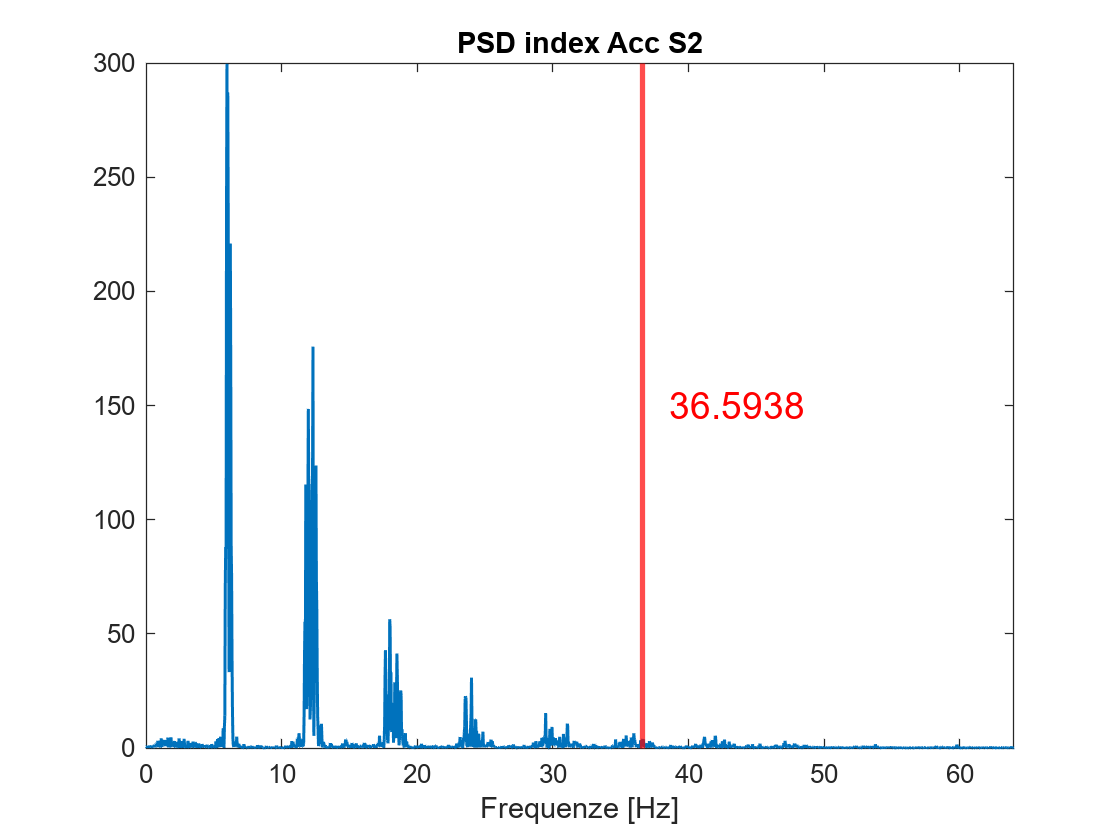

figure()
plot(f_acc, psd_acc,'LineWidth',1.2)
title('PSD index Acc S2')
hold on
xline(f_max_acc,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_acc(end)])
text(f_max_acc + 2, max(psd_acc)/2, num2str(f_max_acc), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_max_acc_indice_2.jpg', 'jpg');

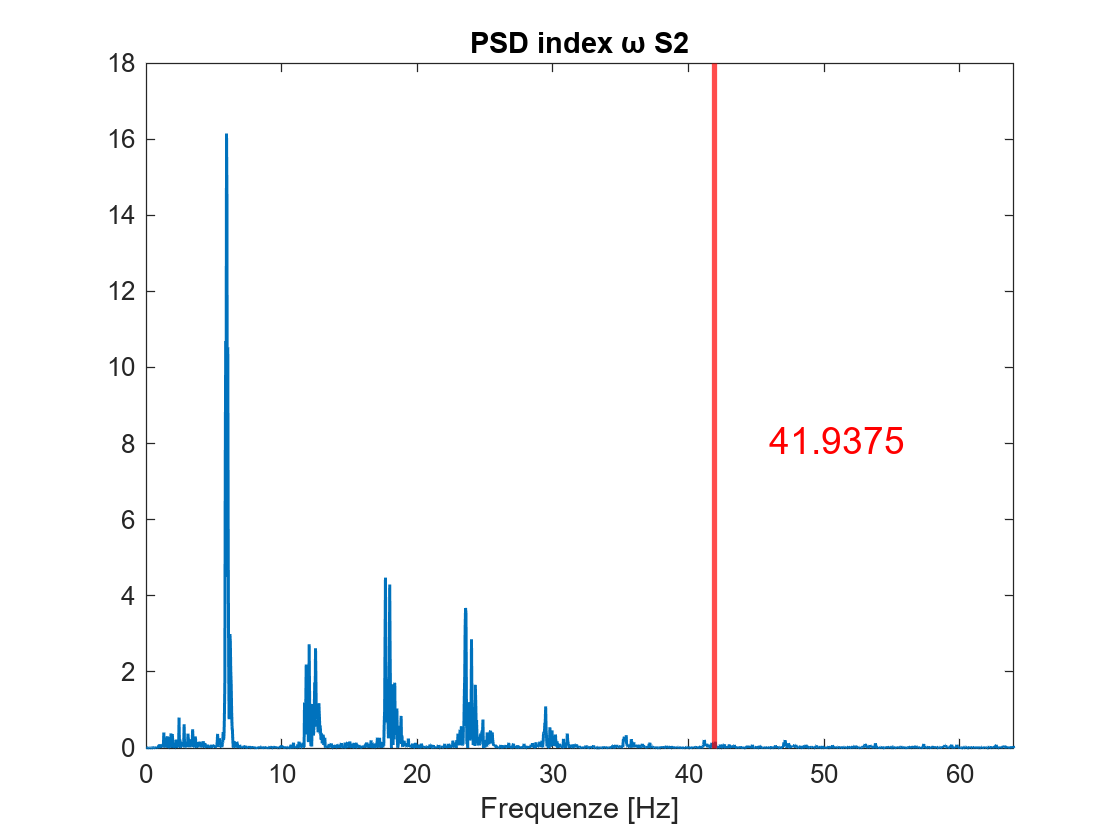

save("f_max_acc_indice_2","f_max_acc")
figure()
plot(f_v, psd_v,'LineWidth',1.2)
title('PSD index ω S2')
hold on
xline(f_max_v,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_v(end)])
text(f_max_v+2 + 2, max(psd_v)/2, num2str(f_max_v), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf,'f_max_v_indice_2.jpg', 'jpg');

save("f_max_v_indice_2","f_max_v")

**THUMB FINGER**

Time and sample frequency extraction.

p_tremor_pollice_tempo = dati.Subj{2}.off.taskAS315.pollice.t;
p_tremor_pollice_f_samp = dati.Subj{2}.off.taskAS315.pollice.fs;

ButterWorth 4th order High-Pass filter (cut-off frequency: 1 Hz).

order = 4;  
low_freq = 1; 
 
nyquist = 0.5 * p_tremor_pollice_f_samp;
low_freq_normalized = low_freq / nyquist;
[b, a] = butter(order, low_freq_normalized, 'high');

Data extraction.

for i=1:3
    p_tremor_pollice_acc(:,i) = dati.Subj{2}.off.taskAS315.pollice.acc(:,i);
    p_tremor_pollice_v(:,i) = dati.Subj{2}.off.taskAS315.pollice.gyro(:,i);   
end


Acceleration and Angular Velocity modules.

p_tremor_pollice_vec_acc(:) = sqrt(p_tremor_pollice_acc(:,1).^2+p_tremor_pollice_acc(:,2).^2+p_tremor_pollice_acc(:,3).^2);
p_tremor_pollice_vec_v(:) = sqrt(p_tremor_pollice_v(:,1).^2+p_tremor_pollice_v(:,2).^2+p_tremor_pollice_v(:,3).^2);

Filter application.

p_tremor_pollice_filt_vec_acc = filtfilt(b,a,p_tremor_pollice_vec_acc);
p_tremor_pollice_filt_vec_v = filtfilt(b,a,p_tremor_pollice_vec_v);


Computation of PSD (Acceleration). 

[psd_acc, f_acc] = periodogram(p_tremor_pollice_filt_vec_acc,[], [], p_tremor_pollice_f_samp);


The maximum frequency is at 95% of PSD area (Acceleration).

area_tot_acc = trapz(f_acc,psd_acc);
area_95_acc = (95/100)*area_tot_acc;

for j=2:length(psd_acc)
    vettore = psd_acc(1:j);
    f_acc_ = f_acc(1:j);
    area_incr = trapz(f_acc_,vettore);
    if area_incr >= area_95_acc
        f_max_acc = f_acc(j);
        break
    end
end


Computation of PSD (Angular Velocity). 

[psd_v, f_v] = periodogram(p_tremor_pollice_filt_vec_v, [],[], p_tremor_pollice_f_samp);


The maximum frequency is at 95% of PSD area (Angular Velocity).

area_tot_v = trapz(f_v, psd_v);
area_95_v = (95/100)*area_tot_v;

for j=2:length(psd_v)
    vett = psd_v(1:j);
    f_v_ = f_v(1:j);
    area_in = trapz(f_v_,vett);
    if area_in >= area_95_v
        f_max_v= f_v(j);
        break
    end
end 

Maximum frequency (Acceleration).

disp(f_max_acc)

   23.8125



Maximum frequency (Angular Velocity).

disp(f_max_v)

   23.5000



Plots.

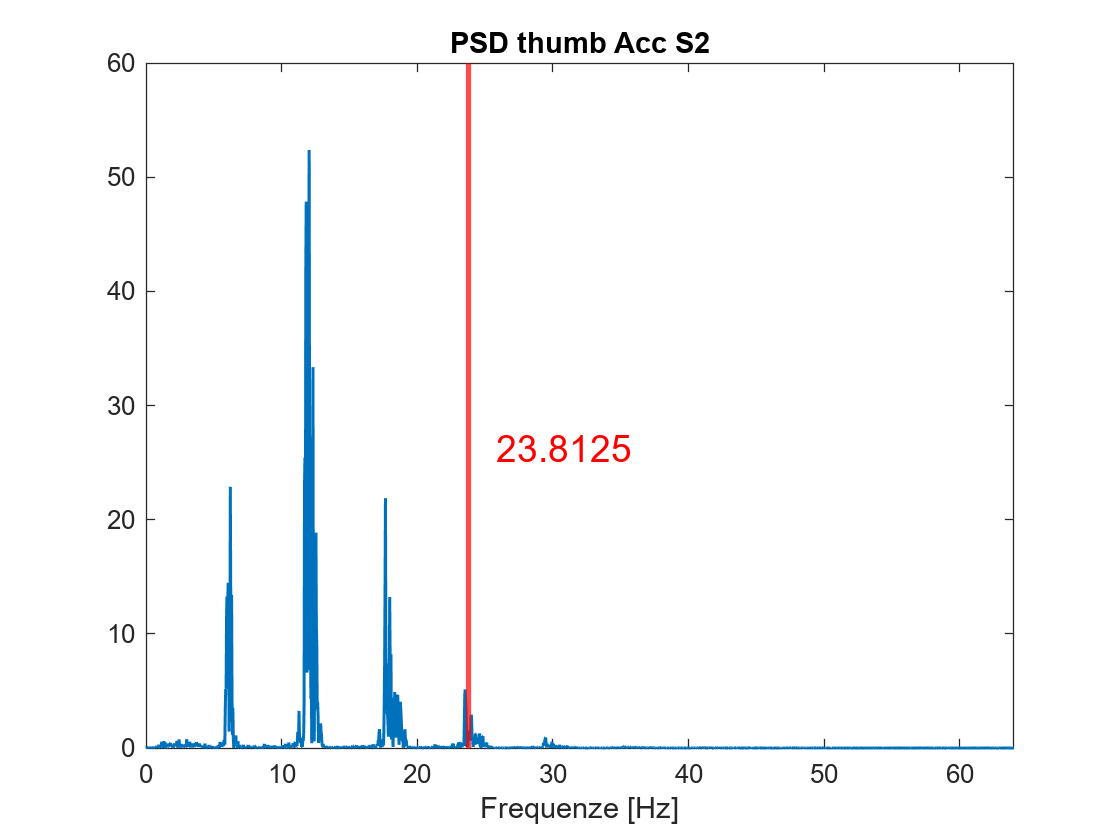

figure()
plot(f_acc, psd_acc,'LineWidth',1.2)
title('PSD thumb Acc S2')
hold on
xline(f_max_acc,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_acc(end)])
text(f_max_acc + 2, max(psd_acc)/2, num2str(f_max_acc), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_max_acc_pollice_2.jpg', 'jpg');

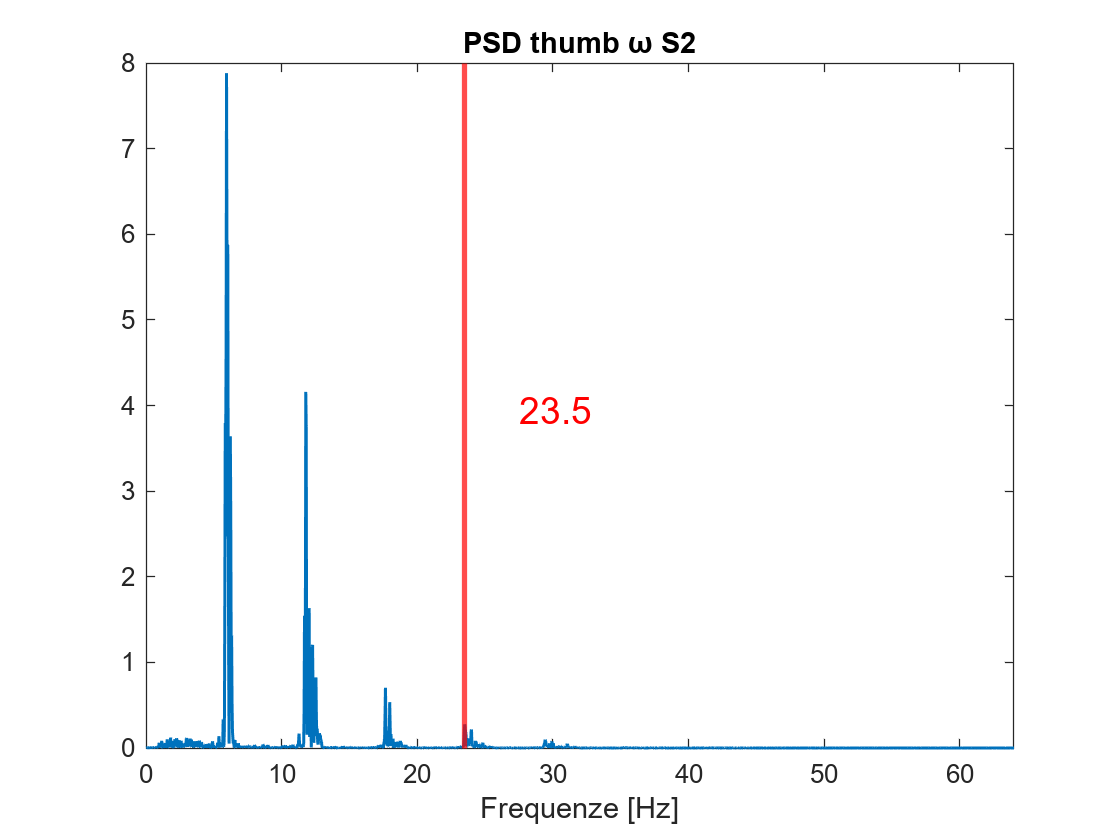

save("f_max_acc_pollice_2","f_max_acc")
figure()
plot(f_v, psd_v,'LineWidth',1.2)
title('PSD thumb ω S2')
hold on
xline(f_max_v,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_v(end)])
text(f_max_v+2 + 2, max(psd_v)/2, num2str(f_max_v), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf,'f_max_v_pollice_2.jpg', 'jpg');

save("f_max_v_pollice_2","f_max_v")

## Metacarpo - Soggetto 2

p_tremor_metacarpo_tempo = dati.Subj{2}.off.taskAS315.metacarpo.t;
p_tremor_metacarpo_f_samp = dati.Subj{2}.off.taskAS315.metacarpo.fs;

ButterWorth 4th order High-Pass filter (cut-off frequency: 1 Hz).

order = 4;  
low_freq = 1;  
 
nyquist = 0.5 * p_tremor_metacarpo_f_samp;
low_freq_normalized = low_freq / nyquist;
[b, a] = butter(order, low_freq_normalized, 'high');

Data extraction.

for i=1:3
    p_tremor_metacarpo_acc(:,i) = dati.Subj{2}.off.taskAS315.metacarpo.acc(:,i);
    p_tremor_metacarpo_v(:,i) = dati.Subj{2}.off.taskAS315.metacarpo.gyro(:,i);   
end


Acceleration and Angular Velocity modules.

p_tremor_metacarpo_vec_acc(:) = sqrt(p_tremor_metacarpo_acc(:,1).^2+p_tremor_metacarpo_acc(:,2).^2+p_tremor_metacarpo_acc(:,3).^2);
p_tremor_metacarpo_vec_v(:) = sqrt(p_tremor_metacarpo_v(:,1).^2+p_tremor_metacarpo_v(:,2).^2+p_tremor_metacarpo_v(:,3).^2);

Filter application.

p_tremor_metacarpo_filt_vec_acc = filtfilt(b,a,p_tremor_metacarpo_vec_acc);
p_tremor_metacarpo_filt_vec_v = filtfilt(b,a,p_tremor_metacarpo_vec_v);


Computation of PSD (Acceleration). 

[psd_acc, f_acc] = periodogram(p_tremor_metacarpo_filt_vec_acc,[], [], p_tremor_metacarpo_f_samp);


The maximum frequency is at 95% of PSD area (Acceleration).

area_tot_acc = trapz(f_acc,psd_acc);
area_95_acc = (95/100)*area_tot_acc;

for j=2:length(psd_acc)
    vettore = psd_acc(1:j);
    f_acc_ = f_acc(1:j);
    area_incr = trapz(f_acc_,vettore);
    if area_incr >= area_95_acc
        f_max_acc = f_acc(j);
        break
    end
end


Computation of PSD (Angular Velocity). 

[psd_v, f_v] = periodogram(p_tremor_metacarpo_filt_vec_v, [],[], p_tremor_metacarpo_f_samp);


The maximum frequency is at 95% of PSD area (Angular Velocity).

area_tot_v = trapz(f_v, psd_v);
area_95_v = (95/100)*area_tot_v;

for j=2:length(psd_v)
    vett = psd_v(1:j);
    f_v_ = f_v(1:j);
    area_in = trapz(f_v_,vett);
    if area_in >= area_95_v
        f_max_v= f_v(j);
        break
    end
end 

Maximum frequency (Acceleration).

disp(f_max_acc)

   24.4688



Maximum frequency (Angular Velocity).

disp(f_max_v)

   18.0312



Plots.

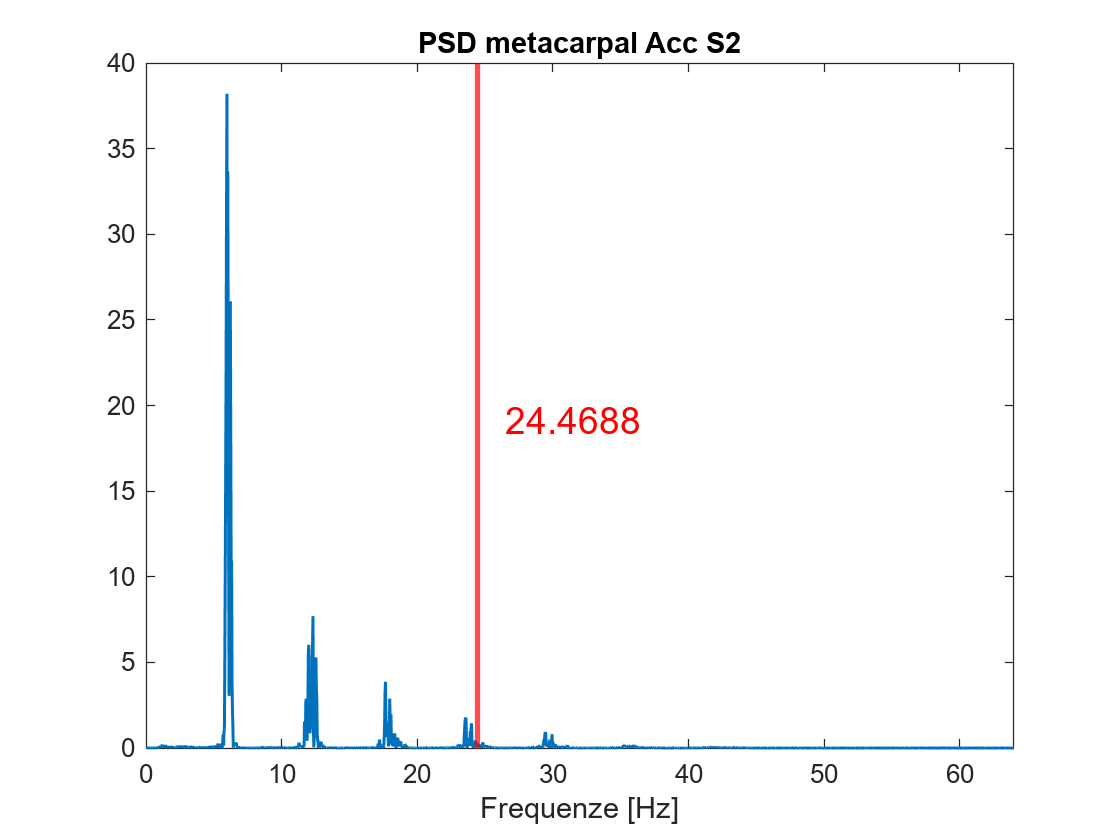

figure()
plot(f_acc, psd_acc,'LineWidth',1.2)
title('PSD metacarpal Acc S2')
hold on
xline(f_max_acc,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_acc(end)])
text(f_max_acc + 2, max(psd_acc)/2, num2str(f_max_acc), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_max_acc_metacarpo_2.jpg', 'jpg');

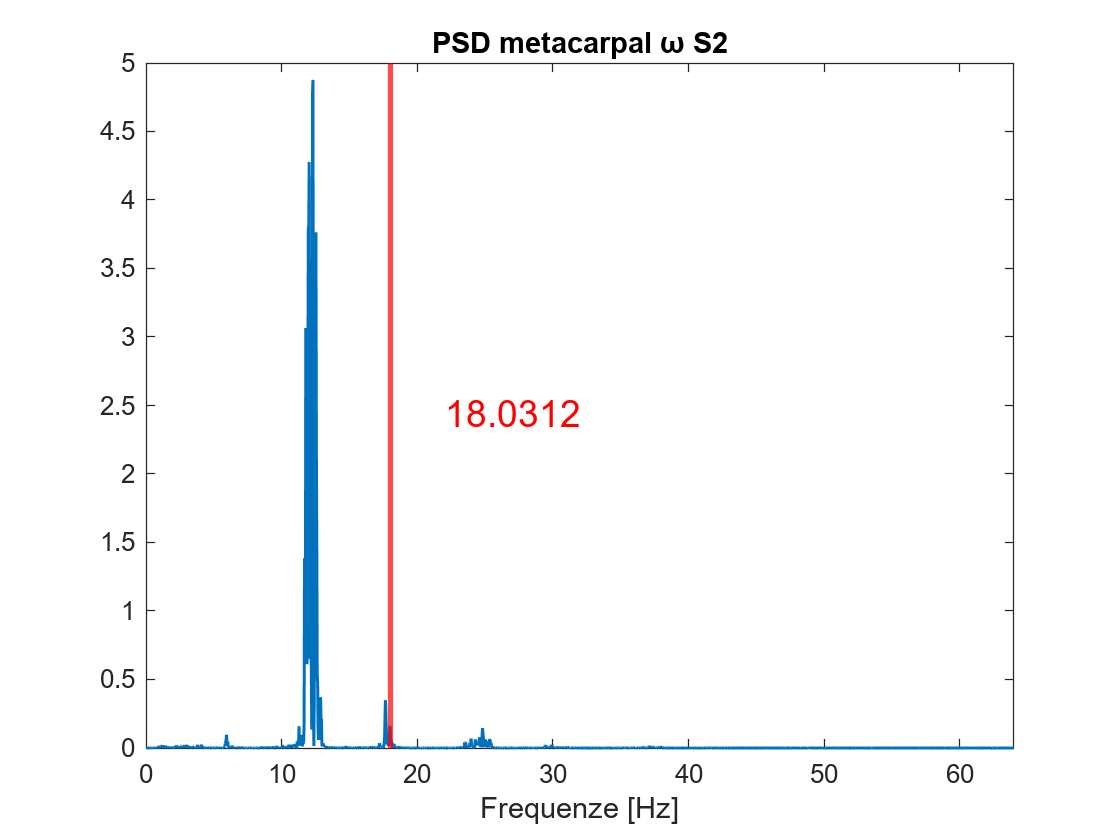

save("f_max_acc_metacarpo_2","f_max_acc")
figure()
plot(f_v, psd_v,'LineWidth',1.2)
title('PSD metacarpal ω S2')
hold on
xline(f_max_v,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_v(end)])
text(f_max_v+2 + 2, max(psd_v)/2, num2str(f_max_v), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf,'f_max_v_metacarpo_2.jpg', 'jpg');

save("f_max_v_metacarpo_2","f_max_v")